clc;clear;close all
addpath("C:\Users\User\Dropbox\Git\Matlab\Adaptive filter\Optimization of Cascaded Parametric Peak and Shelving Filters with Backpropagation Algorithm")
dB20 = @(x) 20*log10(abs(x));

## Class setup

fs = 16000;
type = ["lsf", "peak", "hsf"];
true_parameter = [10, 1000, -5, 500, 3000, 10, 7000];
init_parameter = [8, 900, -1, 400, 3000, 5, 6000];
% type = ["lsf", "hsf"];
% true_parameter = [10, 1000, -10, 7000];
% init_parameter = [9, 1000, -9, 7000];
% type = ["peak"];
% true_parameter = [-10, 500, 1000];
% init_parameter = [-1, 300, 500];
% type = ["lsf"];
% true_parameter = [10, 1000];
% init_parameter = [10, 1000];
learning_rate = abs(true_parameter/1000);
num_fft = 4096;
input = randn(fs*1, 1);
afe = AdaptiveFilterEqualization(fs, type, num_fft, true_parameter, init_parameter, learning_rate, input);
afe.get_tf;
afe.filter_eq;

## Adaptive filter

afe.adapt_parameter;

ans = 10.1100

ans = 10.0100

ans = 10.0100

ans = 10.0300

ans = 9.9900

ans = 9.9900

ans = 10.0100

ans = 9.9900

ans = 10.0300

ans = 9.9900

afe.get_est_tf;

## Figure

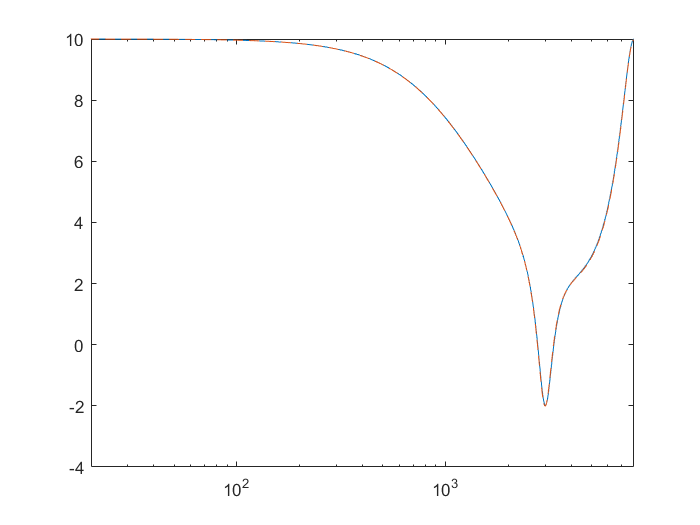

f1 = figure(1);
semilogx(afe.f(1:afe.num_fft/2+1), dB20(afe.tf_eq(1:afe.num_fft/2+1)));
hold on
semilogx(afe.f(1:afe.num_fft/2+1), dB20(afe.tf_est_eq(1:afe.num_fft/2+1)), '--');
xlim([20 fs/2])

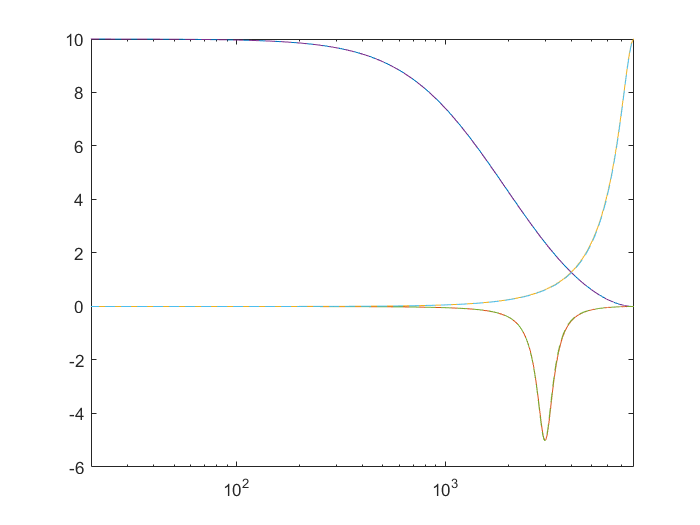


f2 = figure(2);
semilogx(afe.f(1:afe.num_fft/2+1), dB20(afe.tf_ind(1:afe.num_fft/2+1,:)));
hold on
semilogx(afe.f(1:afe.num_fft/2+1), dB20(afe.tf_est_ind(1:afe.num_fft/2+1,:)), '--');
xlim([20 fs/2])

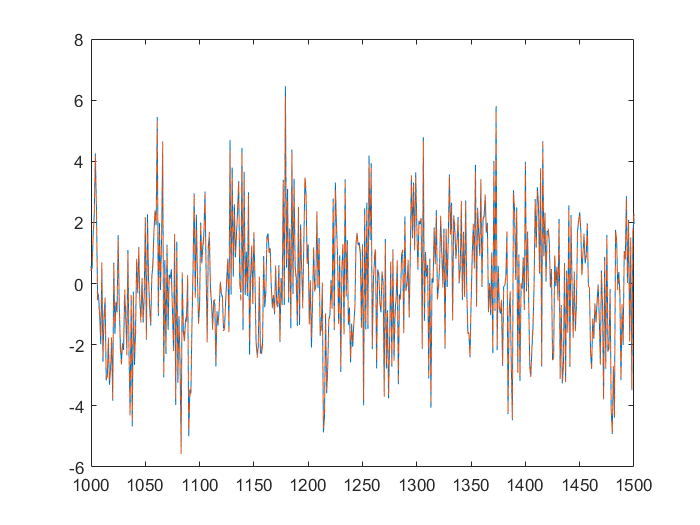


f3 = figure(3);
% plot(afe.input);
% hold on
plot(afe.target);
hold on
plot(afe.output, '--')
xlim([1000 1500])

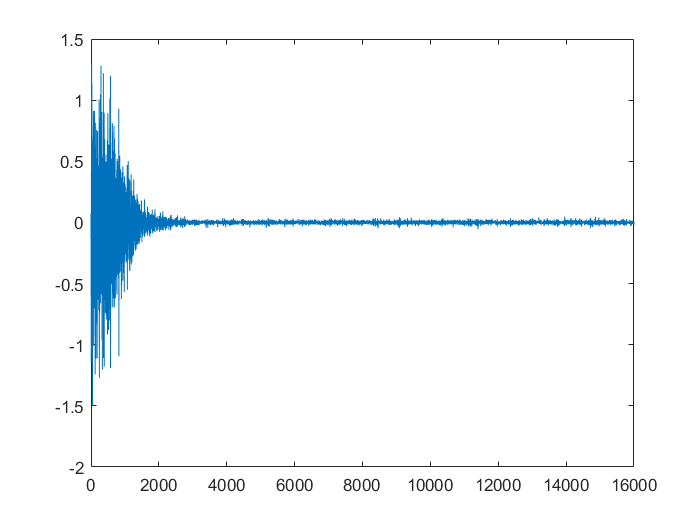


f4 = figure(4);
plot(afe.error)